# Lake inflow modelation

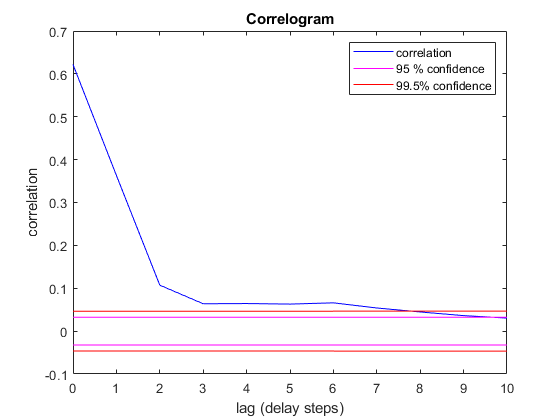

addpath('utils/')
data = load("data\dataPQ_1980_1997.txt");
T = 365;
% Training dataset
years_tr = 10;
u_tr = data(1:T*years_tr,1);  % Input
x_tr = data(1:T*years_tr,2);  % Output
% Validation dataset
u_val = data(T*years_tr+1:end,1);
x_val = data(T*years_tr+1:end,2);

figure; correlogram(x_tr,u_tr,10)

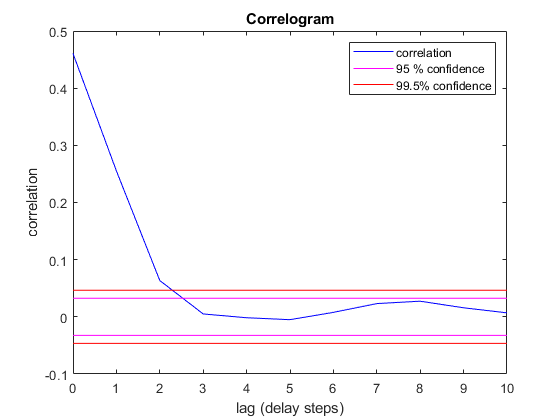

% Normalization
f = 5;
[x_norm, mean_x, sigma_x] = deseasonalize(x_tr, T, f);
[u_norm, mean_u, sigma_u] = deseasonalize(u_tr, T, f);

[x_val_norm, mean_x_val, sigma_x_val] = deseasonalize(x_val, T, f);
[u_val_norm, mean_u_val, sigma_u_val] = deseasonalize(u_val, T, f);

figure; correlogram(x_norm, u_norm, 10)

## AR(1)

y_ar = x_norm(2:end);
M_ar = x_norm(1:end-1);
theta_ar = M_ar\y_ar

theta_ar = 0.7182

x_norm_ar = [x_norm(1); M_ar*theta_ar];
x_ar = x_norm_ar .* sigma_x + mean_x;
r2_ar = r2_performance(x_tr, x_ar, mean_x)

r2_ar = 0.5077

### Validation

M_ar_val = x_val_norm(1:end-1);
x_val_norm_ar = [x_val_norm(1); M_ar_val*theta_ar];
x_val_ar = x_val_norm_ar .* sigma_x_val + mean_x_val;
r2_ar_val = r2_performance(x_val, x_val_ar, mean_x_val)

r2_ar_val = 0.5624

## Proper model ARX(1,1)

y_prop = x_norm(2:end);
M_prop = [x_norm(1:end-1), u_norm(1:end-1)];
theta_prop = M_prop\y_prop

theta_prop =     0.7437
   -0.0548


x_norm_arx_prop = [x_norm(1); M_prop*theta_prop];
x_arx_prop = x_norm_arx_prop .* sigma_x + mean_x;
r2_prop = r2_performance(x_tr, x_arx_prop, mean_x)

r2_prop = 0.5114

### Validation

M_prop_val = [x_val_norm(1:end-1), u_val_norm(1:end-1)];
x_val_norm_arx_prop = [x_val_norm(1); M_prop_val*theta_prop];
x_val_arx_prop = x_val_norm_arx_prop .* sigma_x_val + mean_x_val;
r2_prop_val = r2_performance(x_val, x_val_arx_prop, mean_x_val)

r2_prop_val = 0.5684

## Improper model ARX(1,1)

y_improp = x_norm(2:end);
M_improp = [x_norm(1:end-1), u_norm(2:end)];
theta_improp = M_improp\y_improp

theta_improp =     0.6425
    0.2948


x_norm_arx_improp = [x_norm(1); M_improp*theta_improp];
x_arx_improp = x_norm_arx_improp .* sigma_x + mean_x;
r2_improp = r2_performance(x_tr, x_arx_improp, mean_x)

r2_improp = 0.6983

### Validation

M_improp_val = [x_val_norm(1:end-1), u_val_norm(2:end)];
x_val_norm_arx_improp = [x_val_norm(1); M_improp_val*theta_improp];
x_val_arx_improp = x_val_norm_arx_improp .* sigma_x_val + mean_x_val;
r2_improp_val = r2_performance(x_val, x_val_arx_improp, mean_x_val)

r2_improp_val = 0.7304

## Proper ANN

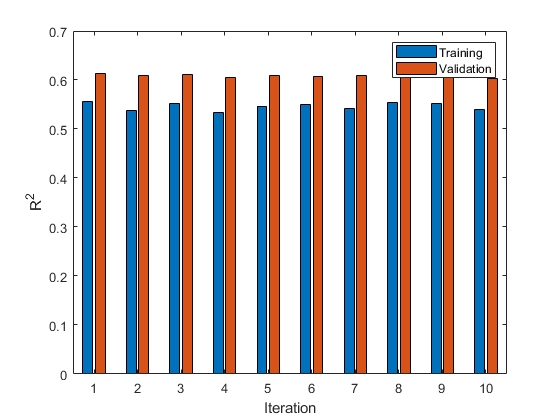

% Train dataset
x_ann = [x_norm(1:end-1), u_norm(1:end-1)]';
y_ann = x_norm(2:end)';
% Validation dataset
x_ann_val = [x_val_norm(1:end-1) u_val_norm(1:end-1)]';

N_runs = 10;
r2_ann_prop = zeros(N_runs, 1);
r2_ann_prop_val = zeros(N_runs, 1);
for i = 1:N_runs
    % ANN Train
    ann_prop_i = feedforwardnet(3);
    ann_prop_i = train(ann_prop_i,x_ann,y_ann);
    
    % view(ann_prop)
    y = ann_prop_i(x_ann);
    y_ann_prop = [x_norm(1); y'];
    x_ann_prop = y_ann_prop .* sigma_x + mean_x;
    
    r2_ann_prop(i) = r2_performance(x_tr, x_ann_prop, mean_x);
    
    % Validation
    y = ann_prop_i(x_ann_val);
    y_ann_prop_val = [x_val_norm(1); y'];
    x_ann_prop_val = y_ann_prop_val .* sigma_x_val + mean_x_val;
    
    r2_ann_prop_val(i) = r2_performance(x_val, x_ann_prop_val, mean_x_val);
    
    if r2_ann_prop_val(i) >= max(r2_ann_prop_val)
        ann_prop = ann_prop_i; % Optimal ANN wrt validation dataset
    end
    
end

figure; 
h = bar([r2_ann_prop, r2_ann_prop_val]);
set(h, {'DisplayName'}, {'Training','Validation'}')
xlabel('Iteration');ylabel('R^2');
legend()

## Improper ANN

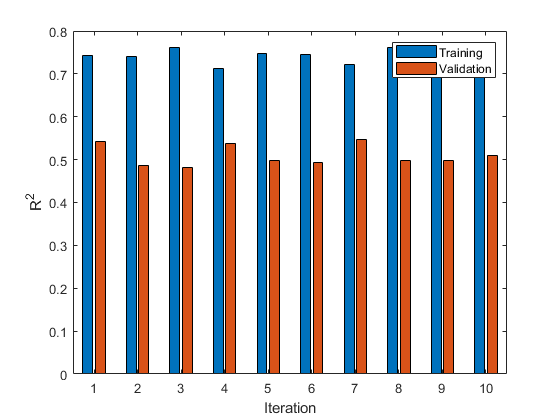

% Train dataset
x_ann = [x_norm(1:end-1), u_norm(2:end)]';
y_ann = x_norm(2:end)';
% Validation dataset
x_ann_val = [x_val_norm(1:end-1) u_val_norm(1:end-1)]';

N_runs = 10;
r2_ann_improp = zeros(N_runs, 1);
r2_ann_improp_val = zeros(N_runs, 1);
for i = 1:N_runs
    % ANN Train
    ann_improp_i = feedforwardnet(3);
    ann_improp_i = train(ann_improp_i,x_ann,y_ann);
    
    % view(ann_prop)
    y = ann_improp_i(x_ann);
    y_ann_improp = [x_norm(1); y'];
    x_ann_improp = y_ann_improp .* sigma_x + mean_x;
    
    r2_ann_improp(i) = r2_performance(x_tr, x_ann_improp, mean_x);
    
    % Validation
    y = ann_improp_i(x_ann_val);
    y_ann_improp_val = [x_val_norm(1); y'];
    x_ann_improp_val = y_ann_improp_val .* sigma_x_val + mean_x_val;
    
    r2_ann_improp_val(i) = r2_performance(x_val, x_ann_improp_val, mean_x_val);
    
    if r2_ann_improp_val(i) >= max(r2_ann_improp_val)
        ann_improp = ann_improp_i; % Optimal ANN wrt validation dataset
    end
    
end

figure; 
h = bar([r2_ann_improp, r2_ann_improp_val]);
set(h, {'DisplayName'}, {'Training','Validation'}')
xlabel('Iteration');ylabel('R^2');
legend()

## Comparison

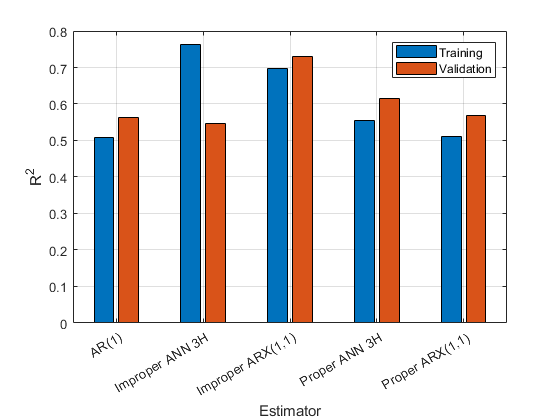

c = categorical({ ...
    'AR(1)', ...
    'Proper ARX(1,1)', ...
    'Improper ARX(1,1)', ...
    'Proper ANN 3H', ...
    'Improper ANN 3H', ...
    });
h = bar(c,[ ...
    r2_ar, r2_ar_val; ...
    r2_prop, r2_prop_val; ...
    r2_improp, r2_improp_val; ...
    max(r2_ann_prop), max(r2_ann_prop_val); ...
    max(r2_ann_improp), max(r2_ann_improp_val); ...
    ]);
set(h, {'DisplayName'}, {'Training','Validation'}')
xlabel('Estimator');ylabel('R^2');
legend()
grid on